# **Absorption in air**

**2023-03-24**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

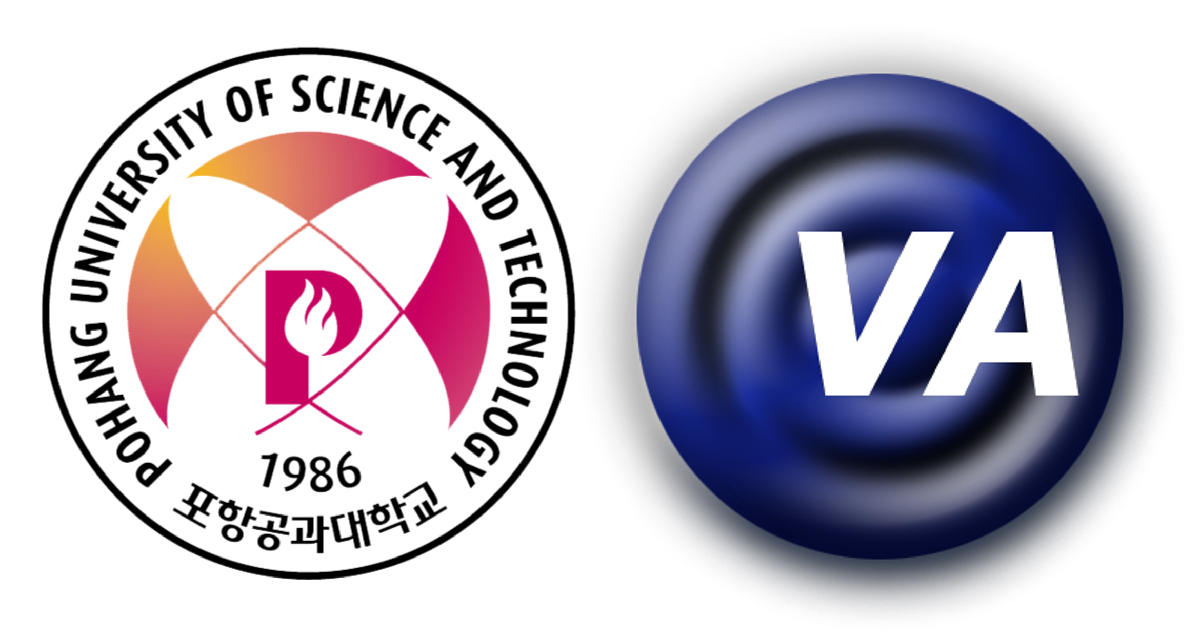

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

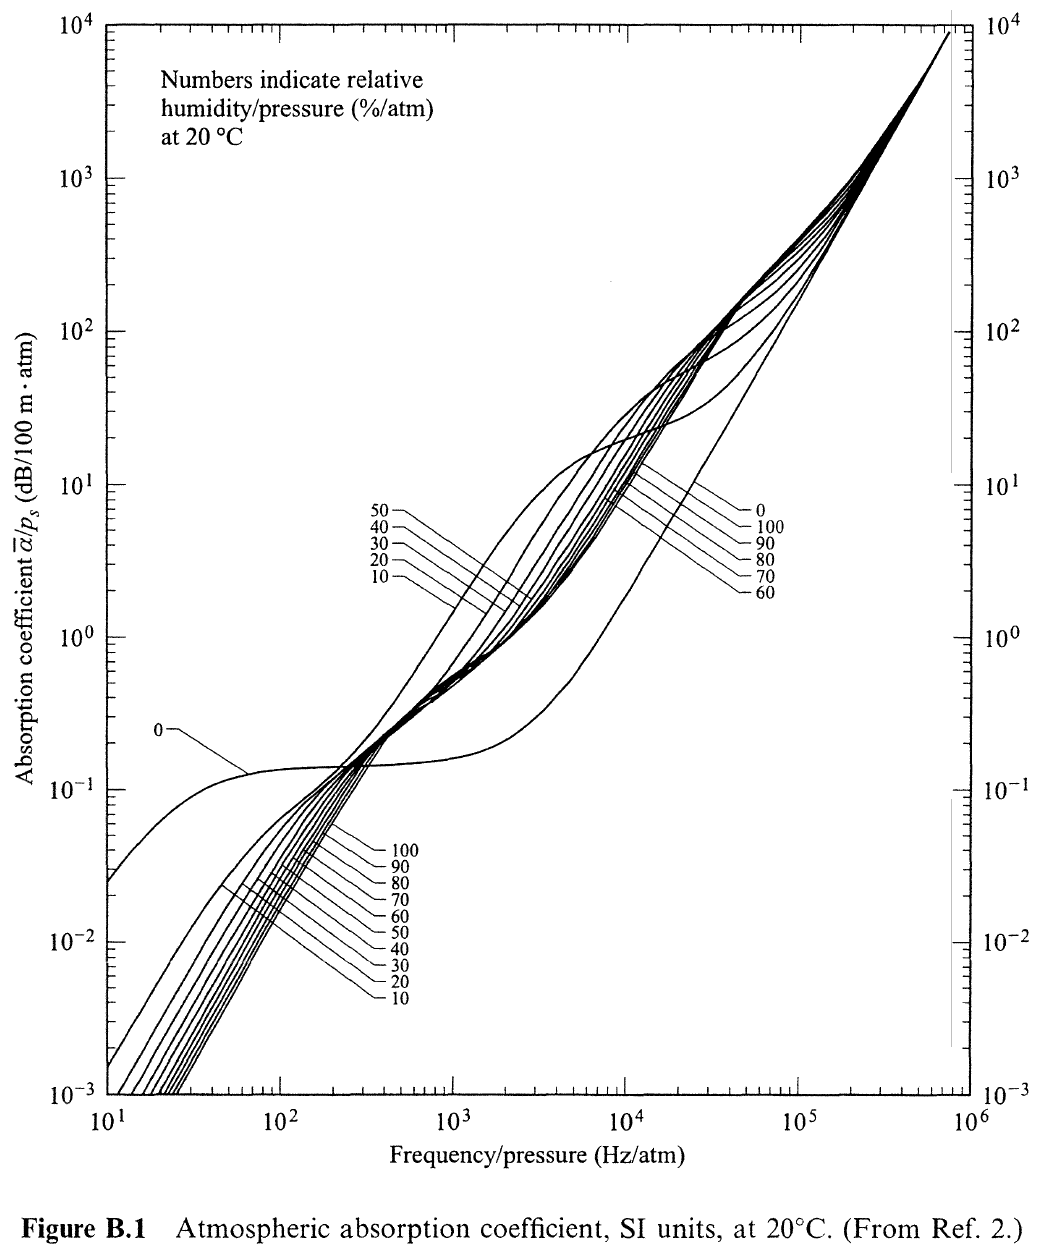

## Reference

### Book

- Blackstock, D. T. (2000). Fundamentals of physical acoustics / by David T. Blackstock. New York, New York : John Wiley & Sons.: 298-315, 513-518.

### Article

- Bass, H. E., et al. (1995). "Atmospheric absorption of sound: Further developments." The Journal of the Acoustical Society of America 97(1): 680-683.

### Standard

- International Organization for Standardization (1993). ISO 9613-1:1993 Acoustics — Attenuation of sound during propagation outdoors — Part 1: Calculation of the absorption of sound by the atmosphere.

- American National Standards Institute (1995). Calculation Of The Absorption Of Sound By The Atmosphere.

### Computer program

- Zechmann, E. (2013). Air Absorption. from https://kr.mathworks.com/matlabcentral/fileexchange/26835-air-absorption.

- Russell, D. A. (2013). "Absorption and Attenuation of Sound in Air." from [https://www.acs.psu.edu/drussell/Demos/Absorption/Absorption.html.](https://www.acs.psu.edu/drussell/Demos/Absorption/Absorption.html.)

Classical absorption 추가할 것.

PA를 만들 때 Shock formation distance와 absorption length와 관계

Rayleigh distance 추가

clear

% Properties of air at 20 [°C]
nu = 1.50e-5;   % Kinematic viscosity, [m^2/s]
Pr = 0.711;     % Prandtl number
gamma = 1.402;  % Specific heat ratio
c0 = 343;       % Sound speed, [m/s]

freq = logspace(1,6,5*100);
hr = 0:10:100;


## Classical absorption coefficient

- FPA p. 314

alpha_c = (2*pi*freq).^2*nu/(2*c0^3)*(4/3+(gamma-1)/Pr);

## The accepted high frequnecy asymptotic expression

- FPA p. 315

alpha_hf = 1.84e-11*freq.^2;

## Absorption coefficient

for i=1:11
    [alpha_dB(i,:), alpha_iso_dB(i,:), c(i,:), c_iso(i,:)] = air_absorption(freq,20,hr(i),1);
end

## Atmospheric absorption coefficient, SI units, at 20 [$\degree \mathrm{C}$]

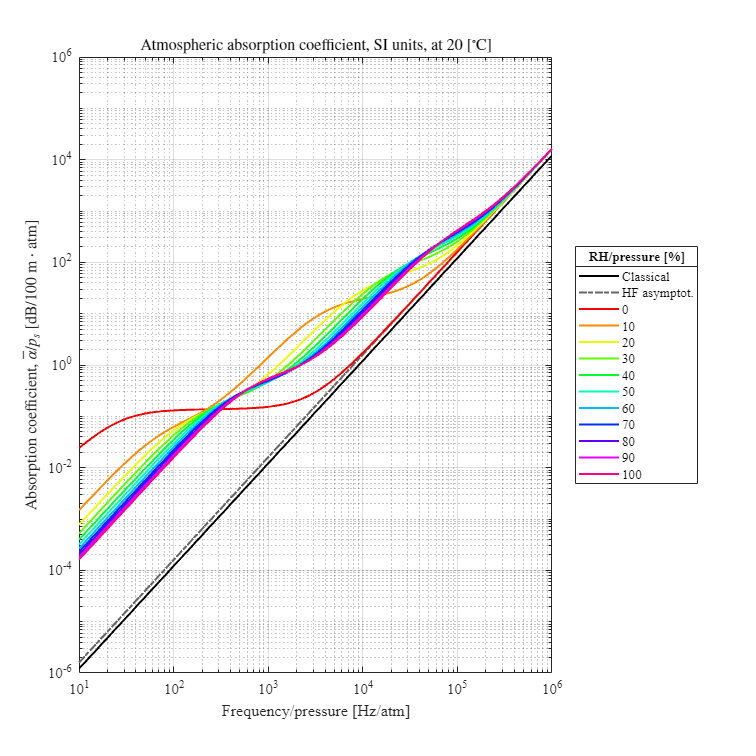

air_absorption_createfigure(freq,hr,alpha_dB*100, 8.686*alpha_c*100, 8.686*alpha_hf*100,...
    'Frequency/pressure [Hz/atm]', ...
    'Absorption coefficient, $\bar{\alpha}/p_s$ [dB/100 m$\cdot$atm]', ...
    'Atmospheric absorption coefficient, SI units, at 20 [$^\circ$C]', ...
    'RH/pressure [%]');

## Atmospheric absorption coefficient, SI units, at 20 [$\degree \mathrm{C}$] and 1 [atm]

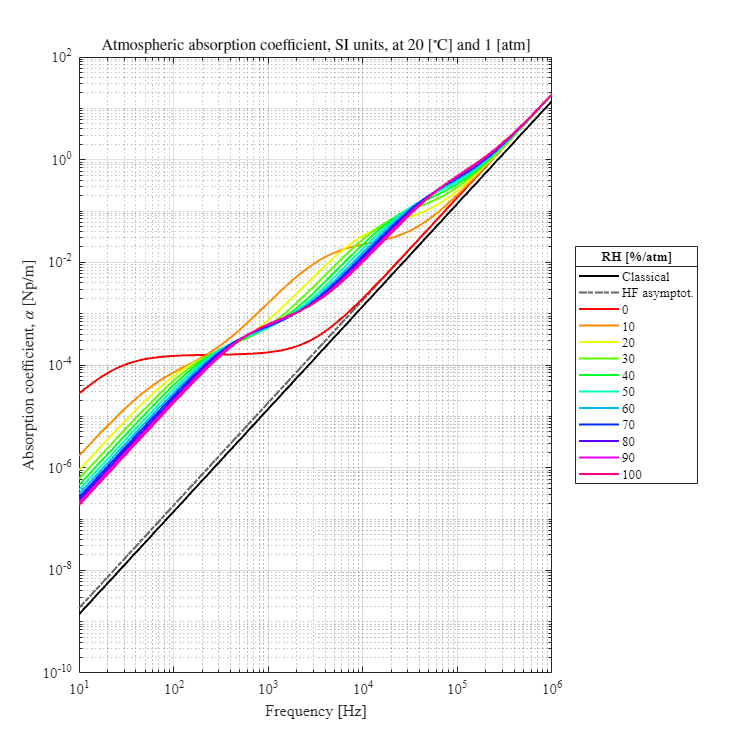

alpha_Np = alpha_dB/8.686;

air_absorption_createfigure(freq,hr,alpha_Np, alpha_c, alpha_hf,...
    'Frequency [Hz]', ...
    'Absorption coefficient, $\alpha$ [Np/m]', ...
    'Atmospheric absorption coefficient, SI units, at 20 [$^\circ$C] and 1 [atm]', ...
    'RH [%/atm]');

## Atmospheric absorption length, SI units, at 20 [$\degree \mathrm{C}$] and 1 [atm]

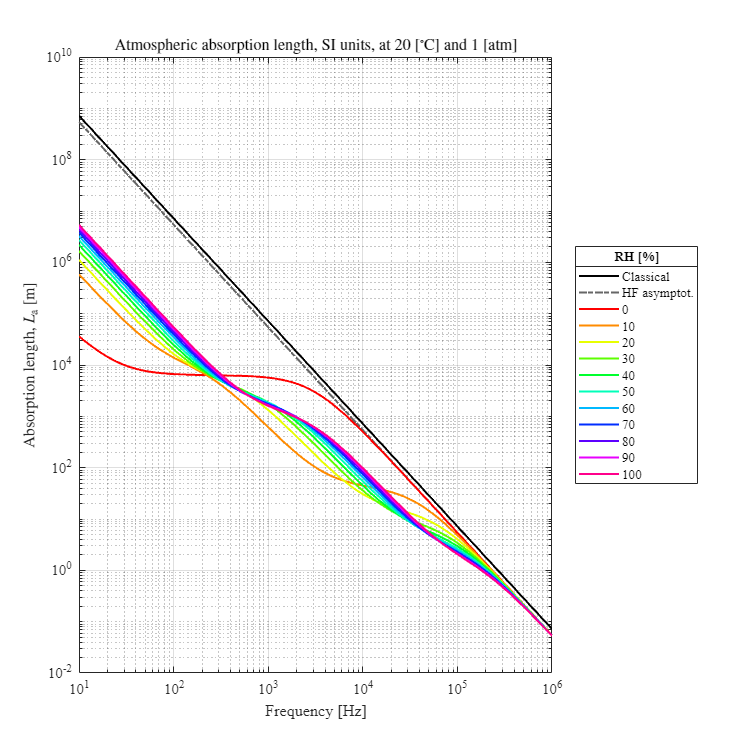

L_alpha = 1./alpha_Np;
L_alpha_c = 1./alpha_c;
L_alpha_hf = 1./alpha_hf;

air_absorption_createfigure(freq,hr,L_alpha, L_alpha_c, L_alpha_hf,...
    'Frequency [Hz]', ...
    'Absorption length, $L_\mathrm{a}$ [m]', ...
    'Atmospheric absorption length, SI units, at 20 [$^\circ$C] and 1 [atm]', ...
    'RH [%]');